# Homework 3

Math 3607, Autumn 2021

Marco LoPiccolo

## Problem 1. 

a.)

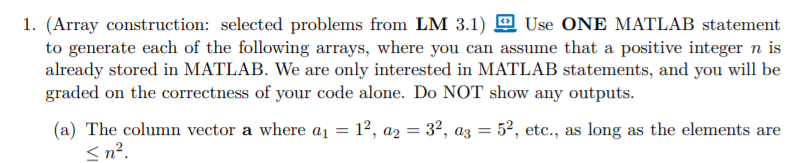

a = ([1:2:n].^2)';

b.)

b = 1./[2:2*n]';

c.)

c = [sin(1:n) cos(n:-1:1)].';

d.)

d = ([1:n].^2 + 1).';

e.)

e = [1:n].^(1./[1:n]).';

f.)

f = mod(0:4*n-1, 4)-2;

g.)

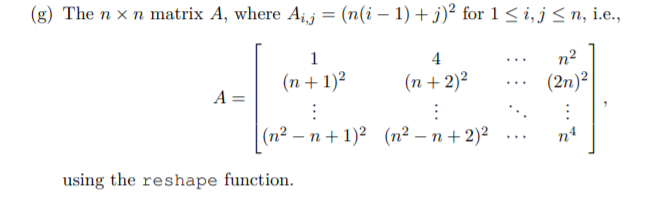

A = (reshape(1:n*n, n, n).^2)';

h.)

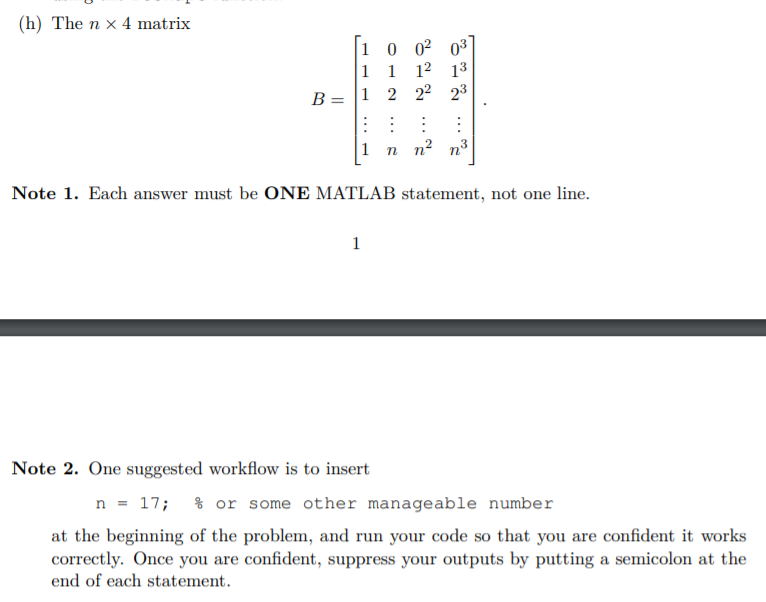

B = [ones(n+1,1) [0:n]' ([0:n].^2)' ([0:n].^3)'];

## Problem 2. 

a.) 

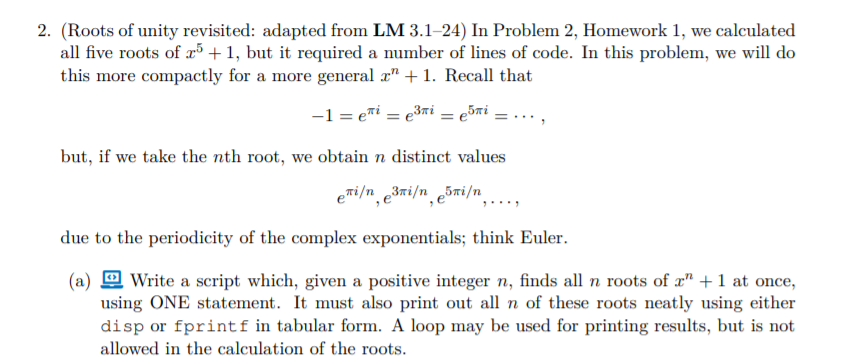

type HW_03_Problem2_Script.m

A = exp((1:2:2*n)*pi*1i/n).';
for k = 1:n
    fprintf('%8.5f + %8.5fi\n', real(A(k)), imag(A(k)));
end


b.)

n = 3

n =      3


run HW_03_Problem2_Script.m

 0.50000 +  0.86603i
-1.00000 +  0.00000i
 0.50000 + -0.86603i


n = 5

n =      5


run HW_03_Problem2_Script.m

 0.80902 +  0.58779i
-0.30902 +  0.95106i
-1.00000 +  0.00000i
-0.30902 + -0.95106i
 0.80902 + -0.58779i


n = 7

n =      7


run HW_03_Problem2_Script.m

 0.90097 +  0.43388i
 0.22252 +  0.97493i
-0.62349 +  0.78183i
-1.00000 +  0.00000i
-0.62349 + -0.78183i
 0.22252 + -0.97493i
 0.90097 + -0.43388i


n = 11

n =     11


run HW_03_Problem2_Script.m

 0.95949 +  0.28173i
 0.65486 +  0.75575i
 0.14231 +  0.98982i
-0.41542 +  0.90963i
-0.84125 +  0.54064i
-1.00000 +  0.00000i
-0.84125 + -0.54064i
-0.41542 + -0.90963i
 0.14231 + -0.98982i
 0.65486 + -0.75575i
 0.95949 + -0.28173i


## Problem 3. 

a.)

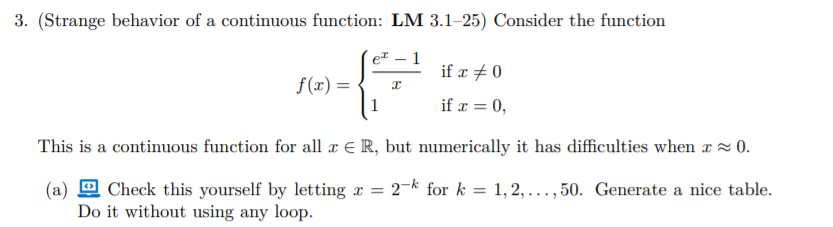

x = (2.^(-(1:50)))';
fx = ((exp(x) - 1) ./ (x));
disp([x, fx])

                       0.5          1.29744254140026
                      0.25          1.13610166675097
                     0.125          1.06518762453461
                    0.0625          1.03191134268575
                   0.03125          1.01578903997129
                  0.015625          1.00785334954789
                 0.0078125          1.00391644242535
                0.00390625          1.00195567061695
               0.001953125          1.00097719859343
              0.0009765625          1.00048844023445
             0.00048828125          1.00024418036628
            0.000244140625          1.00012208024691
           0.0001220703125          1.00006103763917
           6.103515625e-05          1.00003051820022
          3.0517578125e-05          1.00001525894186
         1.52587890625e-05          1.00000762943819
         7.62939453125e-06          1.00000381469727
        3.814697265625e-06          1.00000190734863
       1.9073486328125e-06          1.00000095

b.)

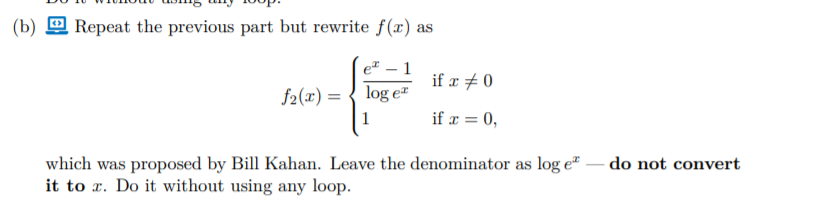

f2x = ((exp(x) - 1) ./ log(exp(x))); 
disp([x, f2x])

                       0.5          1.29744254140026
                      0.25          1.13610166675097
                     0.125          1.06518762453461
                    0.0625          1.03191134268575
                   0.03125          1.01578903997129
                  0.015625          1.00785334954789
                 0.0078125          1.00391644242534
                0.00390625          1.00195567061698
               0.001953125          1.00097719859344
              0.0009765625          1.00048844023453
             0.00048828125          1.00024418036628
            0.000244140625          1.00012208024721
           0.0001220703125          1.00006103763985
           6.103515625e-05          1.00003051819902
          3.0517578125e-05          1.00001525894428
         1.52587890625e-05          1.00000762943334
         7.62939453125e-06          1.00000381470697
        3.814697265625e-06          1.00000190735106
       1.9073486328125e-06          1.00000095

c.)

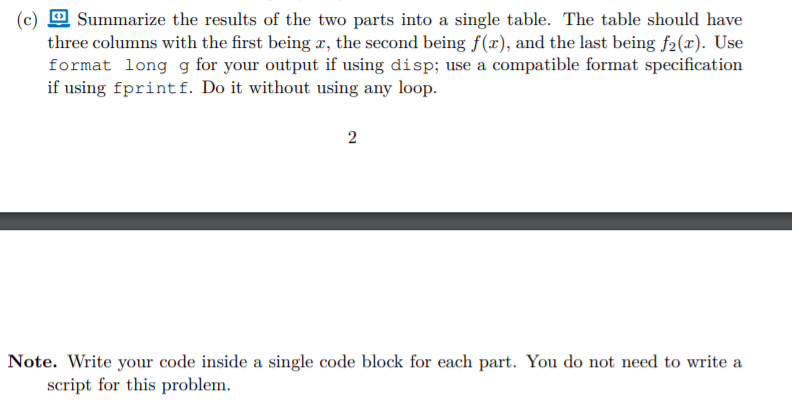

format long g
disp([x, fx, f2x])

                       0.5          1.29744254140026          1.29744254140026
                      0.25          1.13610166675097          1.13610166675097
                     0.125          1.06518762453461          1.06518762453461
                    0.0625          1.03191134268575          1.03191134268575
                   0.03125          1.01578903997129          1.01578903997129
                  0.015625          1.00785334954789          1.00785334954789
                 0.0078125          1.00391644242535          1.00391644242534
                0.00390625          1.00195567061695          1.00195567061698
               0.001953125          1.00097719859343          1.00097719859344
              0.0009765625          1.00048844023445          1.00048844023453
             0.00048828125          1.00024418036628          1.00024418036628
            0.000244140625          1.00012208024691          1.00012208024721
           0.0001220703125          1.00006103763917

## Problem 4. 

a.)

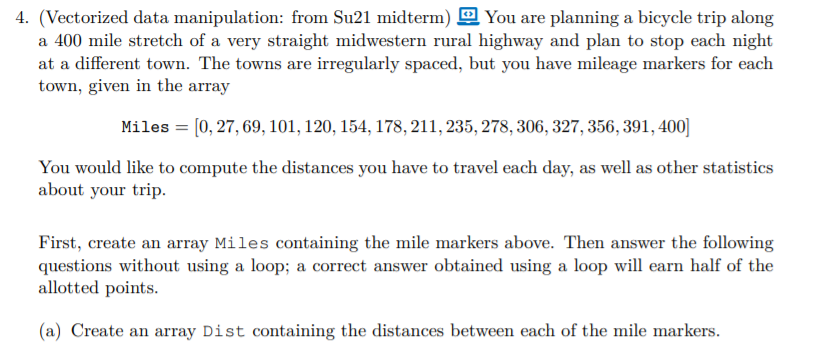

Miles = [0, 27, 69, 101, 120, 154, 178, 211, 235, 278, 306, 327, 356, 391, 400];
Dist = (Miles(2:end) - Miles(1:end-1)).';
disp(Dist);

    27
    42
    32
    19
    34
    24
    33
    24
    43
    28
    21
    29
    35
     9



b.)

b = min(Dist)

b =      9


c.)

c = max(Dist)

c =     43


d.)

d = mean(Dist)

d =           28.5714285714286


e.)

e = Dist(7)

e =     33


f.)

f = Dist ./ 2.';
disp(f);

                      13.5
                        21
                        16
                       9.5
                        17
                        12
                      16.5
                        12
                      21.5
                        14
                      10.5
                      14.5
                      17.5
                       4.5



g.)

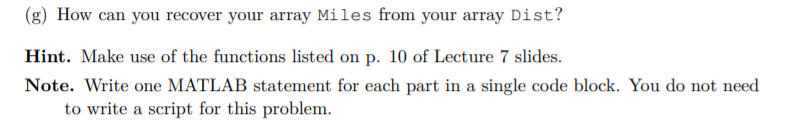

g = [Miles(1); cumsum(Dist)];
disp(g);

     0
    27
    69
   101
   120
   154
   178
   211
   235
   278
   306
   327
   356
   391
   400



## Problem 5. 

a.)

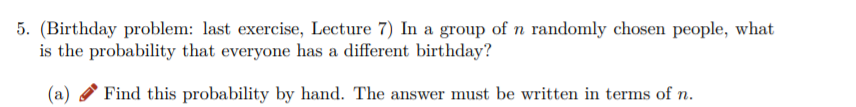

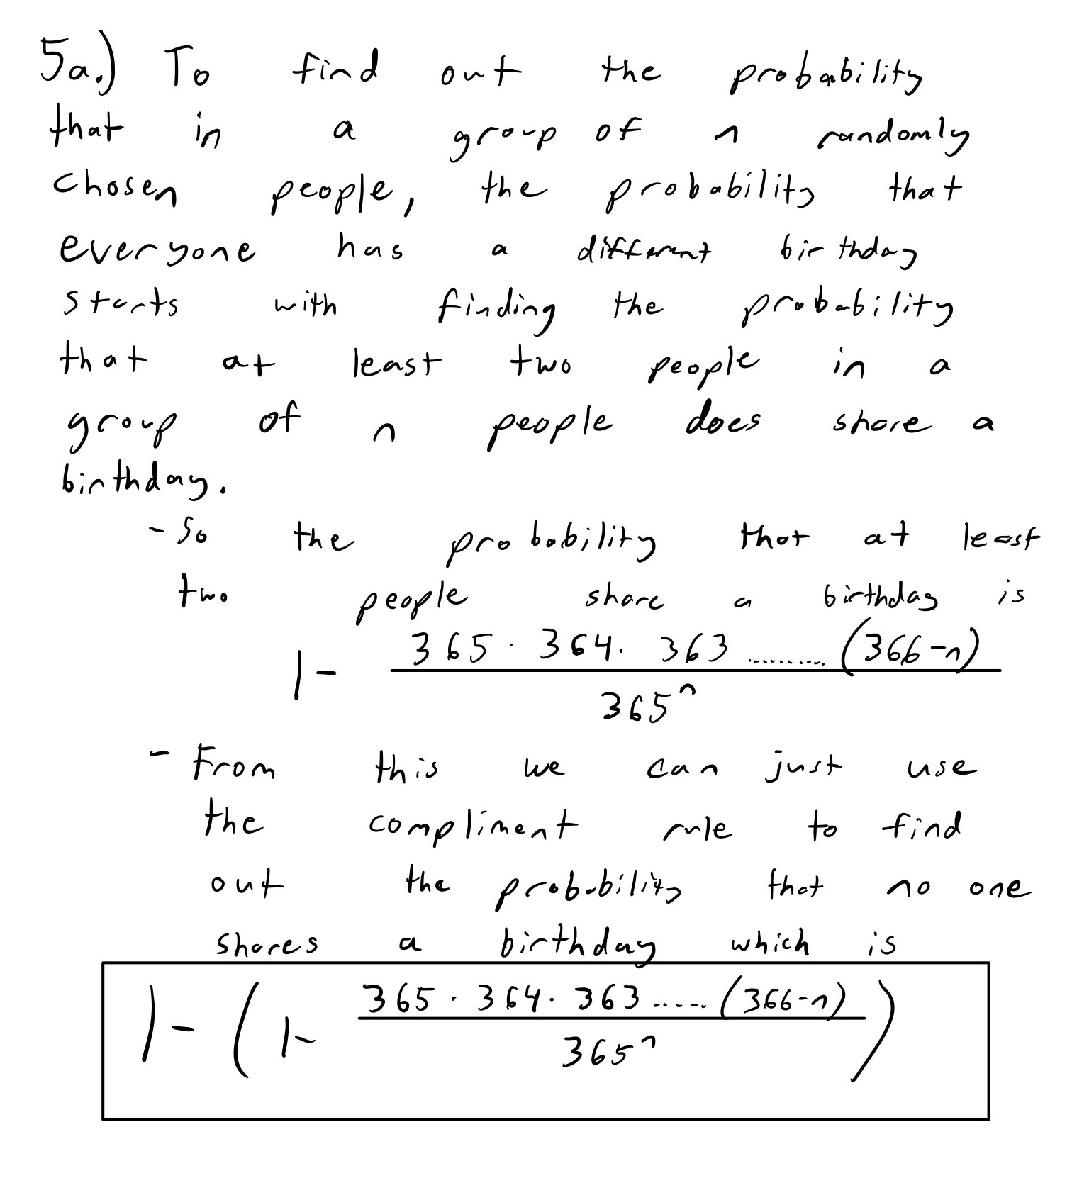

b.)

n = 30;
type HW_03_Problem5b.m

generateRandNumbers = (randi(365, 1, n))
sortedNumbers = (sort(generateRandNumbers))
differenceInNumbers = (diff(sortedNumbers))
findAnyZeroes = find(differenceInNumbers == 0)
numberOfMatches = length(findAnyZeroes)


run HW_03_Problem5b.m

generateRandNumbers =    267    30   306   254   222   221   126   165   263    56   327   249   141   122   350    81   292   116   225   342    11   171   121    86   288   233   201   293   276   210


sortedNumbers =     11    30    56    81    86   116   121   122   126   141   165   171   201   210   221   222   225   233   249   254   263   267   276   288   292   293   306   327   342   350


differenceInNumbers =     19    26    25     5    30     5     1     4    15    24     6    30     9    11     1     3     8    16     5     9     4     9    12     4     1    13    21    15     8



findAnyZeroes =

  1×0 empty double row vector



numberOfMatches =      0


c.)

type HW_03_Problem5c.m

%Generates a matrix with it randomizing the numbers up to 365 with n 
%being the number of birthdays in a single simulation which will be
%the numbers going down each value in each column and that is
%represented in how it is sorted and the columns represent the number of 
%simulations done
%input('Enter the Number of Simulations: ', numberOfSimulations);
generateRandNumbers = (randi(365, n, numberOfSimulations));
sortedNumbers = sort(generateRandNumbers);
differenceInNumbers = (diff(sortedNumbers));
%The createMatch Variable creates a matrix that is the same size as the matrix
%of differenceInNumbers
createMatch = zeros(size(differenceInNumbers));
%identifyNumbersInDiff finds all the index values in the matrix that
%contain the value zero by going down each value in each column and then it
%goes on to the next column and then it displays in a vector where the
%zeroes are
identifyNumbersInDiff = find(differenceInNumbers == 0);
%changes all the places in the matrix of zeros in createMat

d.)

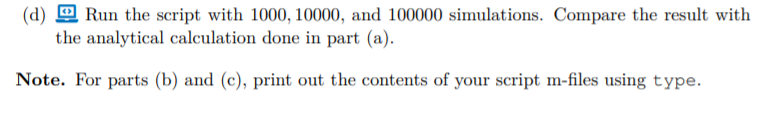

numberOfSimulations = 1000;
run HW_03_Problem5c.m

The Probability of a match is: 0.723
The Probability of no matches is: 0.277


numberOfSimulations = 10000;
run HW_03_Problem5c.m

The Probability of a match is: 0.7092
The Probability of no matches is: 0.2908


numberOfSimulations = 100000;
run HW_03_Problem5c.m

The Probability of a match is: 0.70614
The Probability of no matches is: 0.29386
